## Evaluation script for a trained DQN agent

#### This script loads a previously trained RL agent and evaluates it in the environment. It shows the agent's performance in several test episodes.

clc;
clear all;
close all;

### Environment Configuration and Data Loading

**Note**: It is **CRITICAL** that the parameters and environment definition here are **EXACTLY** the same as those used during training.

fprintf('Loading parameters and defining the environment...\n');

Loading parameters and defining the environment...


%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: /media/jorge/98DC550DDC54E752/code/SIM/code


% Load the same base parameters as in training
Parameters; % Script containing necessary variables 

total_iteration = 1

Wireless packet type: SC


N_y = 4

M_x = 15

M_y = 15

zeta =     0.9800    0.9810    0.9820    0.9830    0.9840    0.9850    0.9860    0.9870    0.9880    0.9890    0.9900    0.9910    0.9920    0.9930    0.9940    0.9950    0.9960    0.9970    0.9980    0.9990


T_coh = 0.0066

N_packets_coh = 16

T = 144

SNR_dB = 11.6443


% Rebuild the EnvPars structure
EnvPars.N = evalin('base','N');
EnvPars.N_x = evalin('base','N_x');
EnvPars.N_y = evalin('base','N_y');
EnvPars.T = evalin('base','T');
EnvPars.T_x = evalin('base','T_x');
EnvPars.T_y = evalin('base','T_y');
EnvPars.SNR_dB = evalin('base','SNR_dB');

EnvPars.theta_min = evalin('base','theta_min');
EnvPars.theta_max = evalin('base','theta_max');
EnvPars.fc = evalin('base','fc');
EnvPars.lambda = evalin('base','lambda');
EnvPars.Ptx_dBm = evalin('base','Ptx_dBm');
EnvPars.Gtx_dBi = evalin('base','Gtx_dBi');
EnvPars.Grx_dBi = evalin('base','Grx_dBi');
EnvPars.txArray.NumElements = evalin('base','txArray.NumElements');
EnvPars.cdl = evalin('base','cdl');
EnvPars.var_noise_dB = evalin('base','var_noise_dB');
EnvPars.r = 0;

EnvPars.d_x = evalin('base','d_x');
EnvPars.pos_SIM = evalin('base','pos_SIM');
EnvPars.pos_MU  = [L_hall*rand(1,1)...
                   W_hall*rand(1,1)...
                   1.5];                 % Mobile user coordinates

EnvPars.maxSteps = EnvPars.T;
EnvPars.tolerance = tolerance;

% Environment variables
n = (1:EnvPars.N);
n_y = ceil(n ./ EnvPars.N_x);
n_x = n - (n_y - 1) .* EnvPars.N_x;
n_psi = n;
n_psi_y = ceil(n_psi ./ EnvPars.N_x);
n_psi_x = n_psi - (n_y - 1) .* EnvPars.N_x;
G_func = @(n,n_psi) exp(-1i*2*pi*(n_psi_x(n_psi)-1)/EnvPars.N_x.*(n_x(n)-1)).* ...
    exp(-1i*2*pi*(n_psi_y(n_psi)-1)/EnvPars.N_y.*(n_y(n)-1));
[n_psi_grid, n_s_grid] = ndgrid(1:EnvPars.N, 1:EnvPars.N);
EnvPars.G = G_func(n_s_grid, n_psi_grid);
t = (1:EnvPars.T);
EnvPars.t_y = ceil(t ./ EnvPars.T_x);
EnvPars.t_x = t - (EnvPars.t_y - 1) .* EnvPars.T_x;
EnvPars.U_func = @(n_, t_n_) exp(1i * ( ...
    -2*pi*(n_x(n_)-1) * (EnvPars.t_x(t_n_)-1) / (EnvPars.N_x*EnvPars.T_x) ...
    -2*pi*(n_y(n_)-1) * (EnvPars.t_y(t_n_)-1) / (EnvPars.N_y*EnvPars.T_y) ));

% Environment object
ObsInfo = rlNumericSpec([EnvPars.N 1]);
ActInfo = rlFiniteSetSpec(1:EnvPars.T);
StepHandle = @(Action, LoggedSignals) stepFunction(Action, LoggedSignals, EnvPars);
ResetHandle = @() resetFunction_random(EnvPars);
env = rlFunctionEnv(ObsInfo, ActInfo, StepHandle, ResetHandle);

% Load trained agent
try
    path_enhanced = fullfile('..', 'Dataset', 'dqn_agent_random_Reward_B.mat');
    load(path_enhanced, 'agent','criticNet');
    fprintf('Trained agent successfully loaded.\n\n');
catch
    error('The agent file "dqn_phase_agent_mejorado.mat" could not be found. Make sure it is in the same folder.');
end

Trained agent successfully loaded.



### Evaluation for a given number of steps

% Parameters
t = 0:delta_time:time_simul;     % time vector in s

EnvPars.tolerance = pi/25;

%% Initialization
Nt = length(t);
pos_MU_traj = zeros(3, Nt);

% Initial position
current_pos = pos_MU_init(:);
current_pos(1) = min(max(current_pos(1), 0), L_hall);
current_pos(2) = min(max(current_pos(2), 0), W_hall);

pos_MU_traj(:,1) = current_pos;

% Initial mobility state
state = "move";   % either "move" or "pause"

% First target waypoint
target_pos = [L_hall*rand; W_hall*rand; current_pos(3)];

% Pause handling
pause_end_time = -inf;

%% Time evolution
for k = 2:Nt
    
    dt = t(k) - t(k-1);
    
    % In case of non-positive time step, keep previous position
    if dt <= 0
        pos_MU_traj(:,k) = pos_MU_traj(:,k-1);
        continue;
    end
    
    if state == "move"
        
        % Vector toward target
        dvec = target_pos(1:2) - current_pos(1:2);
        dist_to_target = norm(dvec);
        travel_dist = MU_speed * dt;
        
        if dist_to_target <= travel_dist
            % Reach waypoint within this time step
            current_pos(1:2) = target_pos(1:2);
            
            % Switch to pause state
            pause_duration = pause_min + (pause_max - pause_min)*rand;
            pause_end_time = t(k) + pause_duration;
            state = "pause";
            
        else
            % Move toward waypoint
            direction = dvec / dist_to_target;
            current_pos(1:2) = current_pos(1:2) + direction * travel_dist;
        end
        
    elseif state == "pause"
        
        % Stay still during pause
        if t(k) >= pause_end_time
            % Pause finished, choose new waypoint and move again
            target_pos = [L_hall*rand; W_hall*rand; current_pos(3)];
            state = "move";
        end
        
    end
    
    % Store position
    pos_MU_traj(:,k) = current_pos;
end

% Enforce constant z-coordinate
pos_MU_traj(3,:) = pos_MU_init(3);


#### Including the channel coherence time

**Description**:In this block we include the number of transmittions along wich the channel is coherent.This is similar to assuming the user keeps the same position.

pos_MU_traj = repelem(pos_MU_traj, 1, floor(N_packets_coh*delta_time/T_coh));

t=linspace(0,time_simul,length(pos_MU_traj(1,:)));

#### Ploting the mobility of the user

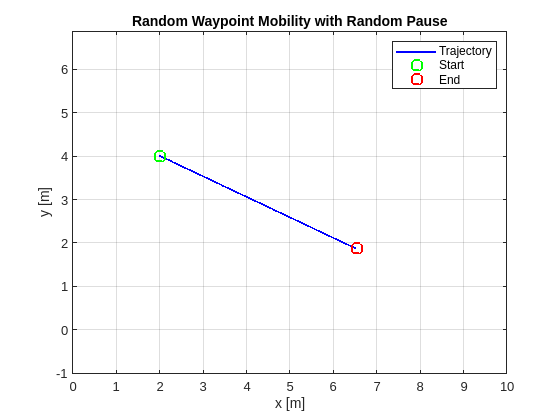

figure;
plot(pos_MU_traj(1,:), pos_MU_traj(2,:), 'b-', 'LineWidth', 1.5); hold on;
plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(pos_MU_traj(1,end), pos_MU_traj(2,end), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
xlim([0 L_hall]);
ylim([0 W_hall]);
xlabel('x [m]');
ylabel('y [m]');
title('Random Waypoint Mobility with Random Pause');
grid on;
axis equal;
legend('Trajectory','Start','End');


% %% Animation of the mobile user trajectory
% 
% figure;
% hold on;
% grid on;
% axis equal;
% xlim([0 L_hall]);
% ylim([0 W_hall]);
% xlabel('$x$ [m]','Interpreter','latex');
% ylabel('$y$ [m]','Interpreter','latex');
% title('Mobile User Random Waypoint Trajectory');
% 
% % Draw hall boundary
% rectangle('Position',[0, 0, L_hall, W_hall], 'EdgeColor','k', 'LineWidth',1.5);
% 
% % Plot full trajectory as dashed reference
% plot(pos_MU_traj(1,:), pos_MU_traj(2,:), '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
% 
% % Initialize animated trajectory and current user marker
% h_traj = plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'b-', 'LineWidth', 2);
% h_user = plot(pos_MU_traj(1,1), pos_MU_traj(2,1), 'ro', ...
%     'MarkerFaceColor','r', 'MarkerSize',8);
% 
% % Optional text showing current time
% h_time = text(L_hall*(1-0.2), 0.91*W_hall, sprintf('$t = %.2f$ [s]', t(1)), ...
%     'FontSize', font, 'Color', 'k','BackgroundColor','w','Interpreter','latex');
% 
% set(gca,'FontSize',font)
% 
% for k = 1:2*N_packets_coh:length(t)
% 
%     % Update traveled path
%     set(h_traj, 'XData', pos_MU_traj(1,1:k), 'YData', pos_MU_traj(2,1:k));
% 
%     % Update current user position
%     set(h_user, 'XData', pos_MU_traj(1,k), 'YData', pos_MU_traj(2,k));
% 
%     % Update time label
%     set(h_time, 'String', sprintf('t = %.2f s', t(k)));
% 
%     drawnow;
% 
%     % Optional real-time pacing
%     if k < length(t)
%         pause((t(k+1) - t(k))/2);
%     end
% end


#### Agent Evaluation

%% Preallocate/collect episode data
actions = [];
rewards = [];
psi_x_est_history = [];
psi_y_est_history = [];
psi_x_real = [];
psi_y_real = [];

% Pre-compute angle trajectory from position trajectory
Nsteps = length(t);
psi_x_traj = zeros(Nsteps, 1);
psi_y_traj = zeros(Nsteps, 1);
for k = 1:Nsteps
    [psi_x_traj(k), psi_y_traj(k)] = computePsiFromPos(pos_MU_traj(:,k), EnvPars);
end

% Stash trajectory + size in EnvPars so step/reset can see it
EnvPars.psi_x_traj = psi_x_traj;
EnvPars.psi_y_traj = psi_y_traj;
EnvPars.maxSteps   = Nsteps;

% Preallocate logs for one long episode
actions          = zeros(Nsteps, 1);
rewards          = zeros(Nsteps, 1);
psi_x_est_log    = zeros(Nsteps, 1);
psi_y_est_log    = zeros(Nsteps, 1);
psi_x_real_log   = zeros(Nsteps, 1);
psi_y_real_log   = zeros(Nsteps, 1);
error_log        = zeros(Nsteps, 1);

% One reset, then one long step loop
[observation, LoggedSignals] = resetFunction_pos(EnvPars);

% criticNet = getModel(getCritic(agent));  % bare dlnetwork, GPU-independent
% path_critic = fullfile('..', 'Dataset', 'dqn_critic_random_Reward_B.mat');
% save(path_critic, 'agent', 'trainingStats', 'criticNet');

isDone = false;
stepCount = 0;
while ~isDone && stepCount < Nsteps
    % [action, ~] = getAction(agent, observation);
    obs_dl      = dlarray(single(observation(:)), 'CB');
    qVals       = extractdata(predict(criticNet, obs_dl));
    [~, action] = max(qVals);   % greedy: highest Q-value action
    if iscell(action), action = action{1}; end

    [nextObs, reward, isDone, LoggedSignals] = ...
        stepFunction_pos(action, LoggedSignals, EnvPars);

    stepCount = stepCount + 1;
    actions(stepCount)        = double(action);
    rewards(stepCount)        = reward;
    psi_x_est_log(stepCount)  = LoggedSignals.psi_x_est;
    psi_y_est_log(stepCount)  = LoggedSignals.psi_y_est;
    psi_x_real_log(stepCount) = LoggedSignals.psi_x_true;
    psi_y_real_log(stepCount) = LoggedSignals.psi_y_true;
    error_log(stepCount)      = LoggedSignals.error_sum;

    observation = nextObs;
end

### Figures

%% Pre-compute per-frame heatmaps for the agent's trajectory
% Reuse the brute-force sweep, once per frame, using (psi_x_real_log(k), psi_y_real_log(k))
% as the probe angle. Stores R_max_array_k for each frame k.

Nframes = numel(psi_x_real_log);   % == Nsteps from your evaluation loop

R_max_per_frame  = zeros(EnvPars.T_x, EnvPars.T_y, Nframes);
opt_tx_per_frame = zeros(Nframes, 1);
opt_ty_per_frame = zeros(Nframes, 1);

for k = 1:Nframes
    a_psi_x_k   = exp(1i * psi_x_real_log(k) * ((1:EnvPars.N_x) - 1))';
    a_psi_y_k   = exp(1i * psi_y_real_log(k) * ((1:EnvPars.N_y) - 1))';
    a_psi_x_y_k = kron(a_psi_y_k, a_psi_x_k);
    
    R_array_k = zeros(EnvPars.T_x, EnvPars.T_y);
    for t_psi = 1:EnvPars.T
        tx_loc  = EnvPars.t_x(t_psi);
        ty_loc  = EnvPars.t_y(t_psi);
        v0_loc  = EnvPars.U_func(1:EnvPars.N, t_psi);
        Up_loc  = diag(v0_loc');
        r_loc   = sqrt(db2pow(EnvPars.SNR_dB)) * EnvPars.G * Up_loc * a_psi_x_y_k;
        R_loc   = reshape(abs(r_loc), [EnvPars.N_x, EnvPars.N_y])';
        R_array_k(tx_loc, ty_loc) = max(R_loc, [], 'all');
    end
    R_max_per_frame(:,:,k) = R_array_k;
    
    [~, idx_k] = max(R_array_k(:));
    [opt_tx_per_frame(k), opt_ty_per_frame(k)] = ind2sub(size(R_array_k), idx_k);
end

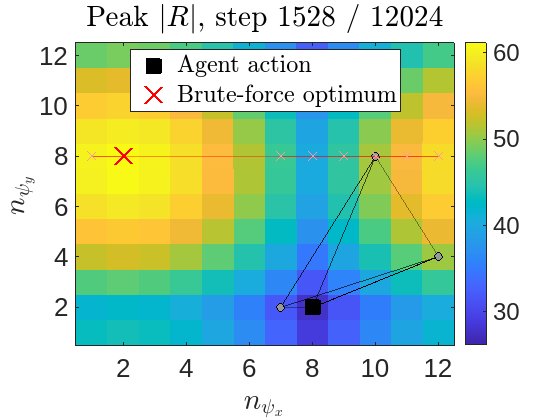


%% Build the agent's chosen-action trajectory in (t_psi_x, t_psi_y) coordinates
% In Pattern B, `actions` is now a 1D vector with one entry per step.
% Each entry is exactly the action taken at that step — no "find last nonzero" needed.
agent_tx = zeros(Nframes, 1);
agent_ty = zeros(Nframes, 1);
for k = 1:Nframes
    a = actions(k);
    agent_tx(k) = EnvPars.t_x(a);   % +1 to match the +1 offset used when filling R_array_k
    agent_ty(k) = EnvPars.t_y(a);
end

%% Animation
figure;
h_img = imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_per_frame(:,:,1)');
axis xy; colorbar; hold on;

% Common color scale across frames
clim([min(R_max_per_frame(:)), max(R_max_per_frame(:))]);

% --- Agent (black) ---
% Trail of past agent actions
h_trail_agent = plot(agent_tx(1), agent_ty(1), '-', ...
                     'Color', [0 0 0 0.4], 'LineWidth', 1.2);
% Past action markers (dim)
h_past_agent  = plot(agent_tx(1), agent_ty(1), 'ko', 'MarkerSize', 6, ...
                     'MarkerFaceColor',[0.6 0.6 0.6], 'MarkerEdgeColor','k');
% Current agent action (bright)
h_agent       = plot(agent_tx(1), agent_ty(1), 'ks', 'MarkerSize', 14, ...
                     'MarkerFaceColor', 'k', 'LineWidth', 1.5);

% --- Brute-force optimum (red) ---
% Trail of past optima
h_trail_opt   = plot(opt_tx_per_frame(1), opt_ty_per_frame(1), '-', ...
                     'Color', [1 0 0 0.4], 'LineWidth', 1.2);
% Past optimum markers (dim red)
h_past_opt    = plot(opt_tx_per_frame(1), opt_ty_per_frame(1), 'rx', ...
                     'MarkerSize', 8, 'LineWidth', 1.0, ...
                     'Color', [1 0.6 0.6]);
% Current optimum (bright red)
h_opt         = plot(opt_tx_per_frame(1), opt_ty_per_frame(1), 'rx', ...
                     'MarkerSize', 16, 'LineWidth', 2.5);

xlabel('$n_{\psi_x}$','Interpreter','latex');
ylabel('$n_{\psi_y}$','Interpreter','latex');
h_title = title(sprintf('Peak $|R|$, step %d / %d', 1, Nframes), ...
                'Interpreter','latex');
legend([h_agent, h_opt], {'Agent action','Brute-force optimum'}, ...
       'Location','best','Interpreter','latex');
set(gca,'FontSize',font);

xlim([0.5 EnvPars.T_x+0.5]); ylim([0.5 EnvPars.T_y+0.5]);

for k = 1:Nframes
    set(h_img, 'CData', R_max_per_frame(:,:,k)');
    
    % Agent: trail, past markers, current
    set(h_trail_agent, 'XData', agent_tx(1:k),          'YData', agent_ty(1:k));
    set(h_past_agent,  'XData', agent_tx(1:max(1,k-1)), 'YData', agent_ty(1:max(1,k-1)));
    set(h_agent,       'XData', agent_tx(k),            'YData', agent_ty(k));
    
    % Optimum: trail, past markers, current
    set(h_trail_opt,   'XData', opt_tx_per_frame(1:k),          'YData', opt_ty_per_frame(1:k));
    set(h_past_opt,    'XData', opt_tx_per_frame(1:max(1,k-1)), 'YData', opt_ty_per_frame(1:max(1,k-1)));
    set(h_opt,         'XData', opt_tx_per_frame(k),            'YData', opt_ty_per_frame(k));
    
    set(h_title, 'String', sprintf('Peak $|R|$, step %d / %d', k, Nframes));
    drawnow;
    if k < Nframes
        pause(0.05);
    end
end

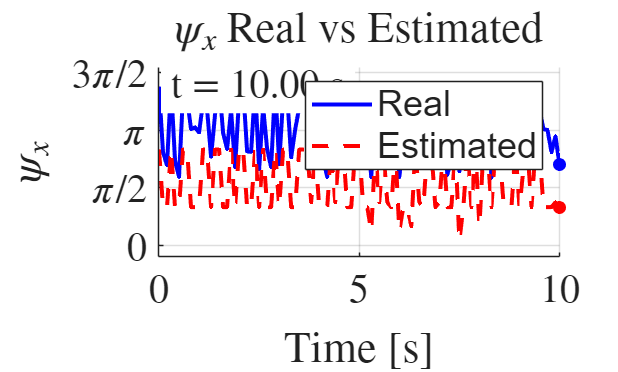



%% Animation of psi_x_real vs psi_x_est

figure;
hold on;
grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('$\psi_x$','Interpreter','latex');
title('$\psi_x$ Real vs Estimated','Interpreter','latex');

% Axis limits (auto-adapt nicely)
xmin = min(t);
xmax = max(t);

ymin = min([psi_x_real(:); psi_x_est(:)]);
ymax = max([psi_x_real(:); psi_x_est(:)]);

% Add small margins
margin = 0.1*(ymax - ymin + eps);
ylim([ymin - margin, ymax + margin]);
xlim([xmin xmax]);

% Initialize lines
h_real = plot(t(1), psi_x_real(1), 'b-', 'LineWidth', 2);
h_est  = plot(t(1), psi_x_est(1), 'r--', 'LineWidth', 2);



% Moving markers (like two actors on stage 🎭)
h_real_pt = plot(t(1), psi_x_real(1), 'bo', 'MarkerFaceColor','b');
h_est_pt  = plot(t(1), psi_x_est(1), 'ro', 'MarkerFaceColor','r');

legend([h_real,h_est],{'Real','Estimated'});

set(gca, 'YTick', [0,pi/2,pi,3*pi/2,2*pi]);
y_ticks=cell(1,5);
x_ticks{1}="$0$";
x_ticks{2}="$\pi/2$";
x_ticks{3}="$\pi$";
x_ticks{4}="$3\pi/2$";
x_ticks{5}="$2\pi$";
set(gca, 'YTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');

% Time label
h_time = text(xmin + 0.02*(xmax-xmin), ymax, ...
    sprintf('$t = %.2f$ s', t(1)), ...
    'FontSize', font, ...
    'BackgroundColor', 'w','Interpreter','latex');

set(gca,'FontSize',font);

%% Animation loop
for k = 1:length(t)
    
    % Update full curves up to time k
    set(h_real, 'XData', t(1:k), 'YData', psi_x_real(1:k));
    set(h_est,  'XData', t(1:k), 'YData', psi_x_est(1:k));
    
    % Update moving markers
    set(h_real_pt, 'XData', t(k), 'YData', psi_x_real(k));
    set(h_est_pt,  'XData', t(k), 'YData', psi_x_est(k));
    
    % Update time text
    set(h_time, 'String', sprintf('t = %.2f s', t(k)));
    
    drawnow;
    
    % Optional real-time pacing
    if k < length(t)
        pause(t(k+1) - t(k));
    end
end

%% Pre-compute per-frame heatmaps for the agent's trajectory
% Reuse the brute-force sweep, once per frame, using (psi_x_real(k), psi_y_real(k))
% as the probe angle. Stores R_max_array_k for each frame k.

R_max_per_frame = zeros(EnvPars.T_x, EnvPars.T_y, numEpisodesToTest);
opt_tx_per_frame = zeros(numEpisodesToTest, 1);
opt_ty_per_frame = zeros(numEpisodesToTest, 1);

for k = 1:numEpisodesToTest
    a_psi_x_k = exp(1i * psi_x_real(k) * ((1:EnvPars.N_x) - 1))';
    a_psi_y_k = exp(1i * psi_y_real(k) * ((1:EnvPars.N_y) - 1))';
    a_psi_x_y_k = kron(a_psi_y_k, a_psi_x_k);
    
    R_array_k = zeros(EnvPars.T_x, EnvPars.T_y);
    for t_psi = 1:EnvPars.T
        tx_loc = EnvPars.t_x(t_psi);
        ty_loc = EnvPars.t_y(t_psi);
        v0_loc = EnvPars.U_func(1:EnvPars.N, t_psi);
        Up_loc = diag(v0_loc');
        r_loc  = sqrt(db2pow(EnvPars.SNR_dB)) * EnvPars.G * Up_loc * a_psi_x_y_k;
        R_loc  = reshape(abs(r_loc), [EnvPars.N_x, EnvPars.N_y])';
        R_array_k(tx_loc+1, ty_loc+1) = max(R_loc, [], 'all');
    end
    R_max_per_frame(:,:,k) = R_array_k;
    
    [~, idx_k] = max(R_array_k(:));
    [opt_tx_per_frame(k), opt_ty_per_frame(k)] = ind2sub(size(R_array_k), idx_k);
end

%% Build the agent's chosen-action trajectory in (t_psi_x, t_psi_y) coordinates
% The agent fires multiple actions per episode; here we pick the LAST action
% taken in each episode (i.e., the policy's converged choice for that user position).
agent_tx = zeros(numEpisodesToTest, 1);
agent_ty = zeros(numEpisodesToTest, 1);
for k = 1:numEpisodesToTest
    nz = find(actions(:,k) ~= 0, 1, 'last');
    if isempty(nz), nz = 1; end
    a = actions(nz, k);
    agent_tx(k) = EnvPars.t_x(a) + 1;   % +1 to match the +1 offset in R_max_array
    agent_ty(k) = EnvPars.t_y(a) + 1;
end

%% Animation
figure;
h_img = imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_per_frame(:,:,1)');
axis xy; colorbar; hold on;

% Common color scale across frames
clim([min(R_max_per_frame(:)), max(R_max_per_frame(:))]);

% Trail of past agent actions
h_trail = plot(agent_tx(1), agent_ty(1), '-', 'Color', [0 0 0 0.4], 'LineWidth', 1.2);
% Past action markers (dim)
h_past  = plot(agent_tx(1), agent_ty(1), 'ko', 'MarkerSize', 6, ...
               'MarkerFaceColor',[0.6 0.6 0.6], 'MarkerEdgeColor','k');
% Current agent action (bright)
h_agent = plot(agent_tx(1), agent_ty(1), 'ks', 'MarkerSize', 14, ...
               'MarkerFaceColor', 'k', 'LineWidth', 1.5);
% Current brute-force optimum
h_opt   = plot(opt_tx_per_frame(1), opt_ty_per_frame(1), 'rx', ...
               'MarkerSize', 16, 'LineWidth', 2.5);

xlabel('$t_{\psi_x}+1$','Interpreter','latex');
ylabel('$t_{\psi_y}+1$','Interpreter','latex');
h_title = title(sprintf('Peak $|R|$, frame %d / %d', 1, numEpisodesToTest), ...
                'Interpreter','latex');
legend([h_agent, h_opt], {'Agent action','Brute-force optimum'}, ...
       'Location','best','Interpreter','latex');
set(gca,'FontSize',font);

xlim([0.5 EnvPars.T_x+0.5]); ylim([0.5 EnvPars.T_y+0.5]);

for k = 1:numEpisodesToTest
    set(h_img,   'CData', R_max_per_frame(:,:,k)');
    set(h_trail, 'XData', agent_tx(1:k), 'YData', agent_ty(1:k));
    set(h_past,  'XData', agent_tx(1:max(1,k-1)), 'YData', agent_ty(1:max(1,k-1)));
    set(h_agent, 'XData', agent_tx(k), 'YData', agent_ty(k));
    set(h_opt,   'XData', opt_tx_per_frame(k), 'YData', opt_ty_per_frame(k));
    set(h_title, 'String', sprintf('Peak $|R|$, frame %d / %d', k, numEpisodesToTest));
    drawnow;
    if k < numEpisodesToTest
        pause(0.05);
    end
end

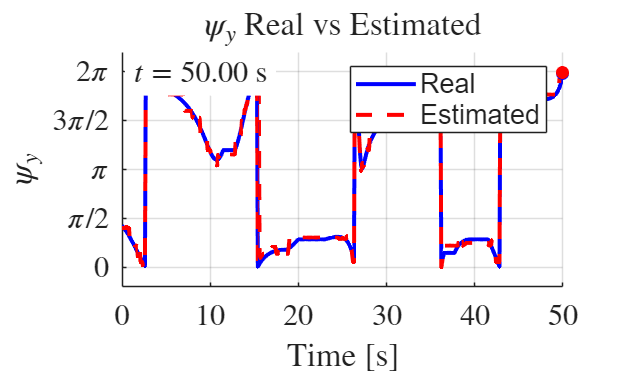

%% Animation of psi_y_real vs psi_y_est

figure;
hold on;
grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('$\psi_y$','Interpreter','latex');
title('$\psi_y$ Real vs Estimated','Interpreter','latex');

% Axis limits (auto-adapt nicely)
xmin = min(t);
xmax = max(t);

ymin = min([psi_y_real(:); psi_y_est(:)]);
ymax = max([psi_y_real(:); psi_y_est(:)]);

% Add small margins
margin = 0.1*(ymax - ymin + eps);
ylim([ymin - margin, ymax + margin]);
xlim([xmin xmax]);

% Initialize lines
h_real = plot(t(1), psi_y_real(1), 'b-', 'LineWidth', 2);
h_est  = plot(t(1), psi_y_est(1), 'r--', 'LineWidth', 2);

% Moving markers
h_real_pt = plot(t(1), psi_y_real(1), 'bo', 'MarkerFaceColor','b');
h_est_pt  = plot(t(1), psi_y_est(1), 'ro', 'MarkerFaceColor','r');

legend([h_real,h_est],{'Real','Estimated'});

% Y ticks in radians
set(gca, 'YTick', [0,pi/2,pi,3*pi/2,2*pi]);
y_ticks = cell(1,5);
y_ticks{1} = "$0$";
y_ticks{2} = "$\pi/2$";
y_ticks{3} = "$\pi$";
y_ticks{4} = "$3\pi/2$";
y_ticks{5} = "$2\pi$";
set(gca, 'YTickLabel', y_ticks, 'TickLabelInterpreter', 'latex');

% Time label
h_time = text(xmin + 0.02*(xmax-xmin), ymax, ...
    sprintf('$t = %.2f$ s', t(1)), ...
    'FontSize', font, ...
    'BackgroundColor', 'w', ...
    'Interpreter','latex');

set(gca,'FontSize',font);

%% Animation loop
for k = 1:length(t)
    
    % Update full curves
    set(h_real, 'XData', t(1:k), 'YData', psi_y_real(1:k));
    set(h_est,  'XData', t(1:k), 'YData', psi_y_est(1:k));
    
    % Update markers
    set(h_real_pt, 'XData', t(k), 'YData', psi_y_real(k));
    set(h_est_pt,  'XData', t(k), 'YData', psi_y_est(k));
    
    % Update time text
    set(h_time, 'String', sprintf('$t = %.2f$ s', t(k)));
    
    drawnow;
    
    if k < length(t)
        pause(t(k+1) - t(k));
    end
end

#### Deterministic Evaluation

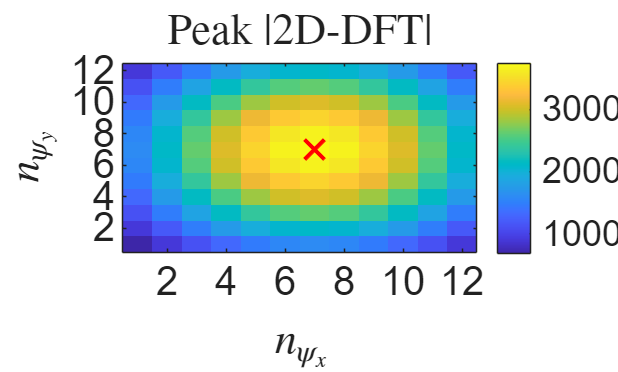

%% Brute-force action-landscape sweep at a fixed true angle
% For a chosen true angle, evaluate all T phase presets t_psi and
% record both the peak DFT magnitude and the resulting estimation error,
% averaged over noise realizations.

% Choose a representative true angle to probe.
% Option A: pick a fixed test angle.
psi_x_true_probe = pi/4;
psi_y_true_probe = pi/4;
% Option B (alternative): use one snapshot of the random-walk trajectory.
% [psi_x_true_probe, psi_y_true_probe] = computeAnglesFromMU(pos_MU_traj(:,1), EnvPars);

Nrep = 50;   % noise realizations per phase preset

R_max_array = zeros(EnvPars.T_x, EnvPars.T_y);
err_array   = zeros(EnvPars.T_x, EnvPars.T_y);

% Pre-build the true steering vector once (independent of t_psi)
a_psi_x = exp(1i * psi_x_true_probe * ((1:EnvPars.N_x) - 1))';
a_psi_y = exp(1i * psi_y_true_probe * ((1:EnvPars.N_y) - 1))';
a_psi_x_y = kron(a_psi_y, a_psi_x);

for t_psi = 1:EnvPars.T
    tx = EnvPars.t_x(t_psi);
    ty = EnvPars.t_y(t_psi);

    % Phase preset (same across noise realizations)
    v0 = EnvPars.U_func(1:EnvPars.N, t_psi);
    Upsilon = diag(v0');
    G_Upsilon = EnvPars.G * Upsilon;

    R_max_acc = 0;
    err_acc   = 0;


    u = 0;%(randn(EnvPars.N,1) + 1i*randn(EnvPars.N,1)) / sqrt(2);
    r = sqrt(db2pow(EnvPars.SNR_dB)) * G_Upsilon * a_psi_x_y + u;

    R = flipud(fliplr(reshape(abs(r), [EnvPars.N_x, EnvPars.N_y])))';
    [maxR, linear_idx] = max(R.^2, [], 'all');
    n_psi_x_max = ceil(linear_idx / EnvPars.N_x);
    n_psi_y_max = linear_idx - (n_psi_x_max - 1) * EnvPars.N_x;

    psi_x_est = mod(2*pi * (n_psi_x_max + tx/EnvPars.T_x) / EnvPars.N_x, 2*pi);
    psi_y_est = mod(2*pi * (n_psi_y_max + ty/EnvPars.T_y) / EnvPars.N_y, 2*pi);

    err = 0.5 * (abs(psi_x_true_probe - psi_x_est) + ...
        abs(psi_y_true_probe - psi_y_est));

    R_max_acc = R_max_acc + maxR;
    err_acc   = err_acc + err;


    R_max_array(tx+1, ty+1) = maxR;
    err_array(tx+1, ty+1)   = err;
end

% Identify the brute-force optima
[~, idx_max_R]   = max(R_max_array(:));
[~, idx_min_err] = min(err_array(:));
[tx_opt_R,   ty_opt_R]   = ind2sub(size(R_max_array), idx_max_R);
[tx_opt_err, ty_opt_err] = ind2sub(size(err_array),   idx_min_err);

%% Plot the two heatmaps side by side
figure;
imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_array');
axis xy; colorbar; hold on;
plot(tx_opt_R, ty_opt_R, 'rx', 'MarkerSize', 14, 'LineWidth', 2);
xlabel('$n_{\psi_x}$','Interpreter','latex');
ylabel('$n_{\psi_y}$','Interpreter','latex');
title('Peak |2D-DFT|','Interpreter','latex');
set(gca,'FontSize',font);

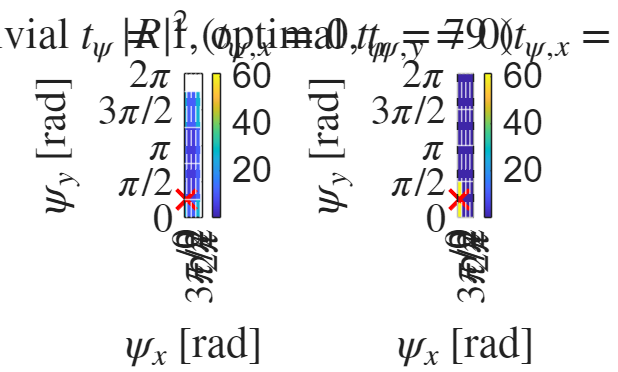


%% Filled cells, blank elsewhere
% Bin width per axis
dx = 2*pi / EnvPars.N_x;
dy = 2*pi / EnvPars.N_y;

% Common colorbar range
cmin = min([R_A_plot(:); R_B_plot(:)]);
cmax = max([R_A_plot(:); R_B_plot(:)]);

% Use a colormap to map R values to RGB triplets
cmap   = parula(256);
mapVal = @(v) cmap(max(1, min(256, round(1 + (v - cmin) / (cmax - cmin) * 255))), :);

x_ticks = 0 : pi/2 : 2*pi;
y_ticks = 0 : pi/2 : 2*pi;
x_tick_labels = arrayfun(@localPiTickLabel, x_ticks, 'UniformOutput', false);
y_tick_labels = arrayfun(@localPiTickLabel, y_ticks, 'UniformOutput', false);

figure;

% --- Subplot A: trivial preset ---
subplot(1,2,1);
hold on; box on;
for ix = 1:EnvPars.N_x
    for iy = 1:EnvPars.N_y
        cx = psi_x_orig_A(ix);
        cy = psi_y_orig_A(iy);
        val = R_A_plot(iy, ix);
        rectangle('Position', [cx - dx/2, cy - dy/2, dx, dy], ...
                  'FaceColor', mapVal(val), 'EdgeColor', 'none');
    end
end
% Tell the axes the true color range so the colorbar is correct
clim([cmin cmax]); colormap(cmap); colorbar;

% White dashed grid lines at cell boundaries (one extra line on each side)
% For case A: boundaries at psi_x_orig_A ± dx/2
x_boundaries_A = [psi_x_orig_A - dx/2, psi_x_orig_A(end) + dx/2];
y_boundaries_A = [psi_y_orig_A - dy/2, psi_y_orig_A(end) + dy/2];
for kx = 1:numel(x_boundaries_A)
    xline(x_boundaries_A(kx), '--w', 'LineWidth', 0.8);
end
for ky = 1:numel(y_boundaries_A)
    yline(y_boundaries_A(ky), '--w', 'LineWidth', 0.8);
end
plot(psi_x_true_probe, psi_y_true_probe, 'rx', 'MarkerSize', 14, 'LineWidth', 2);

xlim([0, 2*pi]); ylim([0, 2*pi]);
xlabel('$\psi_x$ [rad]','Interpreter','latex');
ylabel('$\psi_y$ [rad]','Interpreter','latex');
title(sprintf('$|R|^2$, trivial $t_\\psi=1$ ($t_{\\psi,x}=%d, t_{\\psi,y}=%d$)', tx_A, ty_A), ...
      'Interpreter','latex');
set(gca, 'XTick', x_ticks, 'XTickLabel', x_tick_labels, ...
         'YTick', y_ticks, 'YTickLabel', y_tick_labels, ...
         'TickLabelInterpreter','latex','FontSize',font, ...
         'Layer','top');   % keeps ticks above the rectangles

% --- Subplot B: optimal preset ---
subplot(1,2,2);
hold on; box on;
for ix = 1:EnvPars.N_x
    for iy = 1:EnvPars.N_y
        cx = psi_x_orig_B(ix);
        cy = psi_y_orig_B(iy);
        val = R_B_plot(iy, ix);
        rectangle('Position', [cx - dx/2, cy - dy/2, dx, dy], ...
                  'FaceColor', mapVal(val), 'EdgeColor', 'none');
    end
end
clim([cmin cmax]); colormap(cmap); colorbar;

x_boundaries_B = [psi_x_orig_B - dx/2, psi_x_orig_B(end) + dx/2];
y_boundaries_B = [psi_y_orig_B - dy/2, psi_y_orig_B(end) + dy/2];
for kx = 1:numel(x_boundaries_B)
    xline(x_boundaries_B(kx), '--w', 'LineWidth', 0.8);
end
for ky = 1:numel(y_boundaries_B)
    yline(y_boundaries_B(ky), '--w', 'LineWidth', 0.8);
end

plot(psi_x_true_probe, psi_y_true_probe, 'rx', 'MarkerSize', 14, 'LineWidth', 2);


xlim([0, 2*pi]);
ylim([0, 2*pi]);
xlabel('$\psi_x$ [rad]','Interpreter','latex');
ylabel('$\psi_y$ [rad]','Interpreter','latex');
title(sprintf('$|R|^2$, optimal $t_\\psi=%d$ ($t_{\\psi,x}=%d, t_{\\psi,y}=%d$)', t_psi_B, tx_B, ty_B), ...
      'Interpreter','latex');
set(gca, 'XTick', x_ticks, 'XTickLabel', x_tick_labels, ...
         'YTick', y_ticks, 'YTickLabel', y_tick_labels, ...
         'TickLabelInterpreter','latex','FontSize',font, ...
         'Layer','top');

%% Pre-compute per-frame heatmaps for the agent's trajectory
% Reuse the brute-force sweep, once per frame, using (psi_x_real(k), psi_y_real(k))
% as the probe angle. Stores R_max_array_k for each frame k.

R_max_per_frame = zeros(EnvPars.T_x, EnvPars.T_y, numEpisodesToTest);
opt_tx_per_frame = zeros(numEpisodesToTest, 1);
opt_ty_per_frame = zeros(numEpisodesToTest, 1);

for k = 1:numEpisodesToTest
    a_psi_x_k = exp(1i * psi_x_real(k) * ((1:EnvPars.N_x) - 1))';
    a_psi_y_k = exp(1i * psi_y_real(k) * ((1:EnvPars.N_y) - 1))';
    a_psi_x_y_k = kron(a_psi_y_k, a_psi_x_k);
    
    R_array_k = zeros(EnvPars.T_x, EnvPars.T_y);
    for t_psi = 1:EnvPars.T
        tx_loc = EnvPars.t_x(t_psi);
        ty_loc = EnvPars.t_y(t_psi);
        v0_loc = EnvPars.U_func(1:EnvPars.N, t_psi);
        Up_loc = diag(v0_loc');
        r_loc  = sqrt(db2pow(EnvPars.SNR_dB)) * EnvPars.G * Up_loc * a_psi_x_y_k;
        R_loc  = reshape(abs(r_loc), [EnvPars.N_x, EnvPars.N_y])';
        R_array_k(tx_loc+1, ty_loc+1) = max(R_loc, [], 'all');
    end
    R_max_per_frame(:,:,k) = R_array_k;
    
    [~, idx_k] = max(R_array_k(:));
    [opt_tx_per_frame(k), opt_ty_per_frame(k)] = ind2sub(size(R_array_k), idx_k);
end

%% Build the agent's chosen-action trajectory in (t_psi_x, t_psi_y) coordinates
% The agent fires multiple actions per episode; here we pick the LAST action
% taken in each episode (i.e., the policy's converged choice for that user position).
agent_tx = zeros(numEpisodesToTest, 1);
agent_ty = zeros(numEpisodesToTest, 1);
for k = 1:numEpisodesToTest
    nz = find(actions(:,k) ~= 0, 1, 'last');
    if isempty(nz), nz = 1; end
    a = actions(nz, k);
    agent_tx(k) = EnvPars.t_x(a) + 1;   % +1 to match the +1 offset in R_max_array
    agent_ty(k) = EnvPars.t_y(a) + 1;
end

%% Animation
figure;
h_img = imagesc(1:EnvPars.T_x, 1:EnvPars.T_y, R_max_per_frame(:,:,1)');
axis xy; colorbar; hold on;

% Common color scale across frames
clim([min(R_max_per_frame(:)), max(R_max_per_frame(:))]);

% Trail of past agent actions
h_trail = plot(agent_tx(1), agent_ty(1), '-', 'Color', [0 0 0 0.4], 'LineWidth', 1.2);
% Past action markers (dim)
h_past  = plot(agent_tx(1), agent_ty(1), 'ko', 'MarkerSize', 6, ...
               'MarkerFaceColor',[0.6 0.6 0.6], 'MarkerEdgeColor','k');
% Current agent action (bright)
h_agent = plot(agent_tx(1), agent_ty(1), 'ks', 'MarkerSize', 14, ...
               'MarkerFaceColor', 'k', 'LineWidth', 1.5);
% Current brute-force optimum
h_opt   = plot(opt_tx_per_frame(1), opt_ty_per_frame(1), 'rx', ...
               'MarkerSize', 16, 'LineWidth', 2.5);

xlabel('$t_{\psi_x}+1$','Interpreter','latex');
ylabel('$t_{\psi_y}+1$','Interpreter','latex');
h_title = title(sprintf('Peak $|R|$, frame %d / %d', 1, numEpisodesToTest), ...
                'Interpreter','latex');
legend([h_agent, h_opt], {'Agent action','Brute-force optimum'}, ...
       'Location','best','Interpreter','latex');
set(gca,'FontSize',font);

xlim([0.5 EnvPars.T_x+0.5]); ylim([0.5 EnvPars.T_y+0.5]);

for k = 1:numEpisodesToTest
    set(h_img,   'CData', R_max_per_frame(:,:,k)');
    set(h_trail, 'XData', agent_tx(1:k), 'YData', agent_ty(1:k));
    set(h_past,  'XData', agent_tx(1:max(1,k-1)), 'YData', agent_ty(1:max(1,k-1)));
    set(h_agent, 'XData', agent_tx(k), 'YData', agent_ty(k));
    set(h_opt,   'XData', opt_tx_per_frame(k), 'YData', opt_ty_per_frame(k));
    set(h_title, 'String', sprintf('Peak $|R|$, frame %d / %d', k, numEpisodesToTest));
    drawnow;
    if k < numEpisodesToTest
        pause(0.05);
    end
end

#### Functions

% Functions

function score = evarilos_score(m, M_min, M_max, weight)
    % EVARILOS Benchmarking Handbook scoring function
    % m      : measured metric value (scalar or vector)
    % M_min  : minimal acceptable value (biggest acceptable error)
    % M_max  : maximal acceptable value (desired average localization error)
    % weight : weighting factor (default = 1 if not provided)

    if nargin < 4
        weight = 1; % default weight
    end

    % Linear translation function
    raw_score = 10 * (m - M_min) ./ (M_max - M_min);

    % Clip between 0 and 10
    clipped_score = max(0, min(10, raw_score));

    % Apply weighting factor
    score = weight * clipped_score;
end

function addingPathParentFolderByName(targetName)
    %Place the matlab directory at the right position
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function s = localPiTickLabel(v)
    if v == 0
        s = '$0$';
        return;
    end
    % Express v as p/q * pi in lowest terms
    ratio = v / pi;          % e.g. 0.5, 1, 1.5, 2, 2.5, ...
    [num, den] = rat(ratio, 1e-9);
    if den == 1
        if num == 1
            s = '$\pi$';
        else
            s = sprintf('$%d\\pi$', num);
        end
    elseif num == 1
        s = sprintf('$\\pi/%d$', den);
    else
        s = sprintf('$%d\\pi/%d$', num, den);
    end
end

function [psi_x, psi_y] = computePsiFromPos(pos_MU, EnvPars)
    % Geometry: vector from SIM to MU. SIM on the ceiling, array in the
    % horizontal (xy) plane, z-axis pointing down toward the floor.
    
    delta = pos_MU(:) - EnvPars.pos_SIM(:);   % column vector
    rng   = norm(delta);
    
    % Direction cosines along the array's x and y axes
    u_x = delta(1) / rng;
    u_y = delta(2) / rng;
    
    % Electrical angles (assuming d_y = d_x)
    psi_x = mod(2*pi * EnvPars.d_x * u_x / EnvPars.lambda, 2*pi);
    psi_y = mod(2*pi * EnvPars.d_x * u_y / EnvPars.lambda, 2*pi);
end

#### Alternative evaluation

% %% Simulation Configuration
% % For the evaluation, we disable random exploration.
% % The agent will only use the policy it has learned (exploitation).
% agent.AgentOptions.EpsilonGreedyExploration.EpsilonMin = 0;
% agent.AgentOptions.EpsilonGreedyExploration.Epsilon = 0;
% 
% numEpisodesToTest = 5; % Number of test episodes you want to run
% simOptions = rlSimulationOptions('MaxSteps', EnvPars.maxSteps);
% 
% fprintf('Starting evaluation for %d episodes...\n', numEpisodesToTest);
% fprintf('----------------------------------------\n');
% 
% %% Simulation and Visualization Loop
% for episode = 1:numEpisodesToTest
% 
%     % Reset the environment for a new episode
%     % The reset function will generate new random angles psi_x and psi_y
%     observation = reset(env);
% 
%     % Simulate the episode
%     experience = sim(agent, env, simOptions);
% 
%     % Extract episode data for analysis
%     % The experience is stored in the format (Observation, Action, Reward, NextObservation, IsDone)
%     actions = experience.Action.actions.Data;
%     rewards = experience.Reward.Data;
%     observations = experience.Observation.observations.Data;
% 
%     % The final state contains information from the last step, including the true angles
%     finalInfo = experience.LoggedSignals{end};
%     psi_x_true = finalInfo.psi_x_true;
%     psi_y_true = finalInfo.psi_y_true;
% 
%     % Extract the trajectory of the angle estimates
%     psi_x_est_history = squeeze(observations(1,1,:));
%     psi_y_est_history = squeeze(observations(2,1,:));
% 
%     % Display episode statistics
%     stepsTaken = numel(actions);
%     totalReward = sum(rewards);
%     finalError = finalInfo.error_sum;
% 
%     fprintf('Episode %d:\n', episode);
%     fprintf('  - True Angle (psi_x, psi_y): (%.3f, %.3f)\n', psi_x_true, psi_y_true);
%     fprintf('  - Final Estimated Angle:     (%.3f, %.3f)\n', psi_x_est_history(end), psi_y_est_history(end));
%     fprintf('  - Steps taken: %d / %d\n', stepsTaken, EnvPars.maxSteps);
%     fprintf('  - Total final error: %.4f\n', finalError);
%     fprintf('  - Accumulated reward: %.2f\n', totalReward);
%     fprintf('----------------------------------------\n');
% 
%     % Visualize episode results
%     figure('Name', ['Evaluation Episode Results ' num2str(episode)]);
% 
%     % Subplot 1: psi_x estimation trajectory
%     subplot(2, 1, 1);
%     plot(1:stepsTaken, psi_x_est_history, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
%     hold on;
%     yline(psi_x_true, 'r--', 'LineWidth', 2);
%     title(['\psi_x Estimation vs. Steps (Episode ' num2str(episode) ')']);
%     xlabel('Step');
%     ylabel('\psi_x Value');
%     legend('Estimated', 'True');
%     grid on;
% 
%     % Subplot 2: psi_y estimation trajectory
%     subplot(2, 1, 2);
%     plot(1:stepsTaken, psi_y_est_history, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
%     hold on;
%     yline(psi_y_true, 'r--', 'LineWidth', 2);
%     title(['\psi_y Estimation vs. Steps (Episode ' num2str(episode) ')']);
%     xlabel('Step');
%     ylabel('\psi_y Value');
%     legend('Estimated', 'True');
%     grid on;
% 
%     % Optional: Plot the actions taken
%     figure('Name', ['Actions Taken - Episode ' num2str(episode)]);
%     stem(1:stepsTaken, squeeze(actions), 'filled');
%     title('Sequence of Taken Actions (t_{\psi})');
%     xlabel('Step');
%     ylabel('Action Index');
%     grid on;
% end
